## Settings for simulink model initialization and data analysis

close all
clear all
clc
pm_addunit('percent', 0.01, '1');
options = bodeoptions;
options.FreqUnits = 'Hz';

% enable_dclink_precharge = 1;
% enable_high_frequency_analysis = 0;

enable_dclink_precharge = 0;
enable_high_frequency_analysis = 1;

## Model Settings and Initialization

### precharge simulation


if (enable_dclink_precharge == 1)
    precharge_off = 0.2;
    power_on = precharge_off+0.2;
    time_pwm_enable = power_on;
    load_on = time_pwm_enable + 0.35;
    simlength = 3.75;
    t_misura = simlength;
else
    precharge_off = 0;
    power_on = precharge_off;
    time_pwm_enable = power_on;
    load_on = 0;
    simlength = 1.25;
    t_misura = 0.2;
end

### Switching frequencies, sampling time and deadtime

fPWM = 2.5e3*2;
tPWM = 1/fPWM;

dead_time = 0;
m_dead_time = dead_time/tPWM;
delay_modA = 0;
delay_modB = pi; 
delay_modC = pi;

number_of_levels = 5;
phase_shift_unit = -2*pi/number_of_levels;
% phase_shift_unit = 0;
phase_shift_mod11 = 0;
phase_shift_mod12 = 0;
phase_shift_mod21 = phase_shift_unit;
phase_shift_mod22 = phase_shift_unit;
phase_shift_mod31 = 2*phase_shift_unit;
phase_shift_mod32 = 2*phase_shift_unit;
phase_shift_mod41 = 3*phase_shift_unit;
phase_shift_mod42 = 3*phase_shift_unit;
phase_shift_mod51 = 4*phase_shift_unit;
phase_shift_mod52 = 4*phase_shift_unit;

level_carry_mod11 = 0;
level_carry_mod12 = 0;
level_carry_mod21 = 1;
level_carry_mod22 = -1;
level_carry_mod31 = 2;
level_carry_mod32 = -2;
level_carry_mod41 = 3;
level_carry_mod42 = -3;
level_carry_mod51 = 4;
level_carry_mod52 = -4;

ts = 1/fPWM;
if (enable_high_frequency_analysis == 1)
    tc = ts/2500;
else
    tc = ts/250;
end

s=tf('s');
z=tf('z',ts);

Nc = ceil(t_misura/tc);
Ns = ceil(t_misura/ts);


### Open Loop Modulation Index

% m_duty_open_loop = 0.75/2; % udc = 5000
m_duty_open_loop = 0.75; % udc = 3000

### Current sensor endscale, and quantization

Imax_adc = 10.0;
CurrentQuantization = Imax_adc/2^11;

### Voltage sensor endscale, and quantization

Umax_adc = 1000;
VoltageQuantization = Umax_adc/2^11;

### DClink modules

Udc = 3000;
% Udc = 5000;
Lconn = 20e-6;
Rconn = 1e-3;


#### Low Frequency DClink Components

RLC reference values for each flying arm

CFi = 5e-6;
RCFi = 8.2e-3;
Lconn_CFi = 20e-9;
LCFi = 28e-9 + Lconn_CFi;

first arm (max voltage 1kV)

CFc_1 = CFi;
RCFc_1 = RCFi;
LCFc_1 = LCFi;

second arm (max voltage 2kV)

CFc_2 = CFi;
RCFc_2 = RCFi;
LCFc_2 = LCFi;

third arm (max voltage 3kV)

CFc_3 = CFi;
RCFc_3 = RCFi;
LCFc_3 = LCFi;

fourth arm (max voltage 4kV)

CFc_4 = CFi;
RCFc_4 = RCFi;
LCFc_4 = LCFi;

fifth arm (max voltage 5kV)

CFc_51 = CFi*2;
RCFc_51 = RCFi/2;
LCFc_51 = LCFi/2;

CFc_52 = CFi*2;
RCFc_52 = RCFi/2;
LCFc_52 = LCFi/2;

#### High Frequency DClink Components

condensator high frequency capacitance value

CFi_HF = 0.25e-6;
RCFi_HF = 1;
LCFi_HF = 3e-9;

equivalent values for the first arm leg (max voltage 1kV)

CFi_HF_1 = CFi_HF;
RCFi_HF_1 = RCFi_HF;
LCFi_HF_1 = LCFi_HF;

equivalent values for the second arm leg (max voltage 1kV)

CFi_HF_2 = CFi_HF/2;
RCFi_HF_2 = RCFi_HF*2;
LCFi_HF_2 = LCFi_HF*2;

equivalent values for the third arm leg (max voltage 1kV)

CFi_HF_3 = CFi_HF/3;
RCFi_HF_3 = RCFi_HF*3;
LCFi_HF_3 = LCFi_HF*3;

equivalent values for the fourth arm leg (max voltage 1kV)

CFi_HF_4 = CFi_HF/4;
RCFi_HF_4 = RCFi_HF*4;
LCFi_HF_4 = LCFi_HF*4;

equivalent values for the fifth arm leg (max voltage 1kV)

CFi_HF_5 = CFi_HF/5;
RCFi_HF_5 = RCFi_HF*5;
LCFi_HF_5 = LCFi_HF*5;

#### General DClink settings

udc_bez = Udc;
Rbalance = 1e7;
Rprecharge = 5e3;

Vfc1_base = udc_bez/5;
Vfc2_base = 2*Vfc1_base;
Vfc3_base = 3*Vfc1_base;
Vfc4_base = 4*Vfc1_base;

if (enable_dclink_precharge == 1)
    udc_init = 0;
else
    udc_init = udc_bez;
end
VCFc_1_init = udc_init/5;
VCFc_2_init = udc_init/5*2;
VCFc_3_init = udc_init/5*3;
VCFc_4_init = udc_init/5*4;
VCFc_5_init = udc_init;

### LCL switching filter

LFu1 = 2.5e-3; 
RLFu1 = 157*0.05*LFu1;
CFu = (25e-6);
RCFu = (5e-4);
RFu = 10e3;
f0 = 1/(2*pi*sqrt(LFu1*CFu))

f0 =      6.366197723675813e+02

### IGBT/Mosfet and snubber data

Vg_threshold = 2.6;
Rds_on = 280e-3;
Rg_on = 15;
Rg_off = 15;
Eon = 110e-6;
Eoff = 25e-6;
Vdc_switching_losses_ref = 1200;
Ids_switching_losses_ref = 10;
Ron_diode_mosfet = 1e-3;
Vgamma_diode_mosfet = 4.6;
Vgate_base = 15;
Goff_state_mosfet = 1e-6;

Csnubber = 0.15e-6;
Rsnubber = 2200;
Lstray = 5e-9;

JunctionTermalMass = 0.025; % J/K
Rtim = 0.5;
Rth_mosfet_JH = 1 + Rtim; % K/W
thermal_conducibility = 204; % W/(m K)
Rcond = 0.015/thermal_conducibility/(0.0065*0.03)

Rcond =      3.770739064856712e-01

Rth_mosfet_HA = (2+Rcond)*10 % K/W

Rth_mosfet_HA =      2.377073906485671e+01

Tambient = 25; % celsius
DThs_init = 0; % Heat sink initial delta temperature [Celsius]

### Settings for First Order Low Pass Filters

#### LPF 50Hz in state space (for initialization)

fcut = 50;
fof = 1/(s/(2*pi*fcut)+1);
[nfof, dfof] = tfdata(fof,'v');
[nfofd, dfofd]=tfdata(c2d(fof,ts),'v');
fof_z = tf(nfofd,dfofd,ts,'Variable','z');
[A,B,C,D] = tf2ss(nfofd,dfofd);
LVRT_flt_ss = ss(A,B,C,D,ts);
[A,B,C,D] = tf2ss(nfof,dfof);
LVRT_flt_ss_c = ss(A,B,C,D);

#### LPF 161Hz

fcut_161Hz_flt = 161;
g0_161Hz = fcut_161Hz_flt * ts * 2*pi;
g1_161Hz = 1 - g0_161Hz;

#### LPF 500Hz

fcut_500Hz_flt = 500;
g0_500Hz = fcut_500Hz_flt * ts * 2*pi;
g1_500Hz = 1 - g0_500Hz;

#### LPF 75Hz

fcut_75Hz_flt = 75;
g0_75Hz = fcut_75Hz_flt * ts * 2*pi;
g1_75Hz = 1 - g0_75Hz;

#### LPF 50Hz

fcut_50Hz_flt = 50;
g0_50Hz = fcut_50Hz_flt * ts * 2*pi;
g1_50Hz = 1 - g0_50Hz;

#### LPF 10Hz

fcut_10Hz_flt = 10;
g0_10Hz = fcut_10Hz_flt * ts * 2*pi;
g1_10Hz = 1 - g0_10Hz;

#### LPF 4Hz

fcut_4Hz_flt = 4;
g0_4Hz = fcut_4Hz_flt * ts * 2*pi;
g1_4Hz = 1 - g0_4Hz;

#### LPF 1Hz

fcut_1Hz_flt = 1;
g0_1Hz = fcut_1Hz_flt * ts * 2*pi;
g1_1Hz = 1 - g0_1Hz;

#### LPF 0.2Hz

fcut_0Hz2_flt = 0.2;
g0_0Hz2 = fcut_0Hz2_flt * ts * 2*pi;
g1_0Hz2 = 1 - g0_0Hz2;

### Settings for RMS calculus

f_grid = 50;
rms_perios = 1;
n1 = rms_perios/f_grid/ts;
rms_perios = 10;
n10 = rms_perios/f_grid/ts;

### Control System Settings

Vout_ac_rms_nom = 230;
Iout_ac_rms_nom = 4;
margin_factor = 1.5;
I_FS = Iout_ac_rms_nom * sqrt(2) * margin_factor;
V_FS = Vout_ac_rms_nom * sqrt(2) * margin_factor;


### Double Integrator Observer

A = [0 1; 0 0];
Aso = eye(2) + A*ts;
Cso = [1 0];
p2place = exp([-100 -500]*2*pi*ts);
K = (acker(Aso',Cso',p2place))';
kg = K(1);
kw = K(2);
kalman_theta = kg;
kalman_omega = kw;


### PLL

pll_i1 = 80;
pll_p = 1;
Vnom_ac_adc = V_FS;
omega_ref = 2*pi*50;


### Inverter PI control

kp_v_inv = 0.2;
ki_v_inv = 4;
kp_i_inv = 0.2;
ki_i_inv = 4;


### PI/4 phase shift filter 

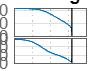


flt_dq = 2/(s/(2*pi*50)+1)^2;
flt_dq_d = c2d(flt_dq,ts);
figure; bode(flt_dq_d); grid on

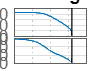

[num50, den50]=tfdata(flt_dq_d,'v');

flt_dq_80Hz = 2/(s/(2*pi*80)+1)^2;
flt_dq_80Hz_d = c2d(flt_dq_80Hz,ts);
figure; bode(flt_dq_80Hz_d); grid on

[num80, den80]=tfdata(flt_dq_80Hz_d,'v');


### kalman observer

f = 50;
w = 2*pi*f;
Ahn = [cos(w*ts) sin(w*ts); -sin(w*ts) cos(w*ts)];
Chn = [1 0];
Bhn = [0 0]';
sys_hn = ss(Ahn,Bhn,Chn,0);
% kalman filter parameters
q1kalman = 1;
q2kalman = ts;
Qkalman = [q1kalman 0; 0 q2kalman];
Rkalman = 1/ts;


### double integrator observer harmonics

Arsoh = [0 1; 0 0];
Crsoh = [1 0];
omega_rsoh = 2*pi*w;
polesrsoh = [-0.4 -0.1]*omega_rsoh;
Lrsoh = acker(Arsoh',Crsoh',polesrsoh)';
Adrsoh = eye(2) + Arsoh*ts;
polesdrsoh = exp(ts*polesrsoh);
Ldrsoh = acker(Adrsoh',Crsoh',polesdrsoh)'

Ldrsoh =      1.847858016314414e-01
     2.827259523490666e+01
